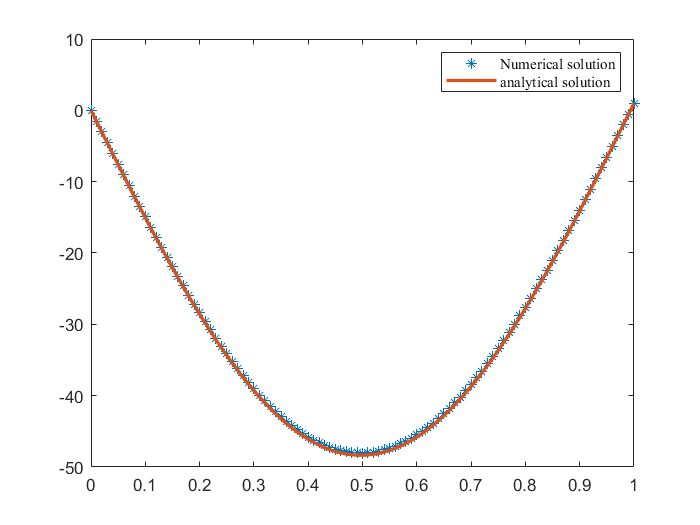

clc,clear,close all
xn = 1;x0 = 0;
n = 100;
h = (xn-x0)/n;
A0 = [1,zeros(1,n)];
A1 = [diag(ones(1,n-1)) , zeros(n-1,2)];
A2 = [zeros(n-1,1),diag(ones(1,n-1))*(10*h^2-2) , zeros(n-1,1)];
A3 = [zeros(n-1,2),diag(ones(1,n-1))];
A4 = [zeros(1,n),1];
A = [A0;A1+A2+A3;A4];
b = [zeros(n,1);1];
y = A\b;
plot(x0:h:xn,y,'*')


syms Y(t)
cond = [Y(0) == 0,Y(1)==1];
f = dsolve(diff(Y,t,2) == -10*Y,cond);
f = matlabFunction(f);
x = x0:h:xn;
hold on
plot(x,f(x),"LineWidth",2)
legend('Numerical solution','analytical solution','Fontname','Times New Roman')
hold off

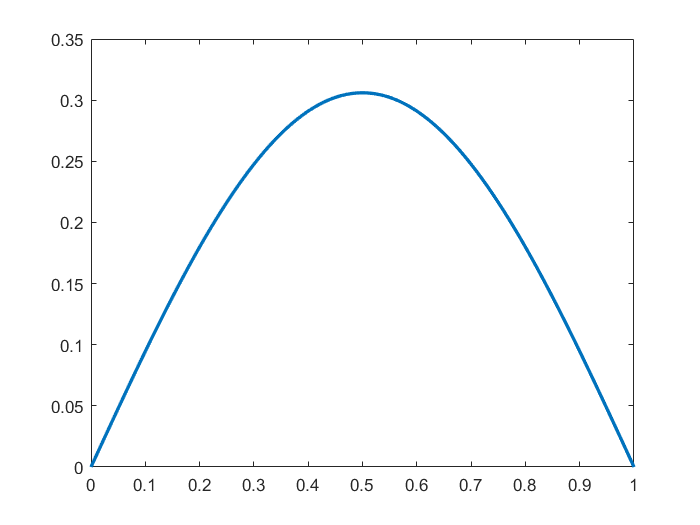


% 横坐标是x，纵坐标是数值解和解析解在该点的误差
error = abs(y'-f(x));
plot(x,error,"LineWidth",2)

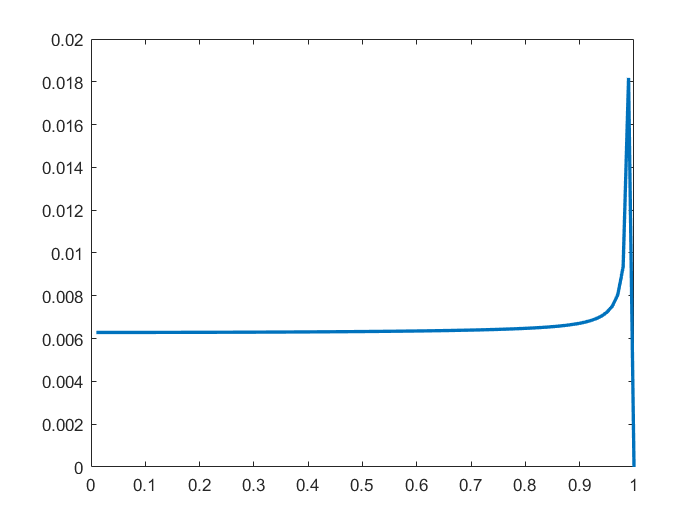


% 横坐标是x，纵坐标是数值解和解析解在该点的相对误差
relative_error = abs(error./f(x));
plot(x,relative_error,"LineWidth",2)

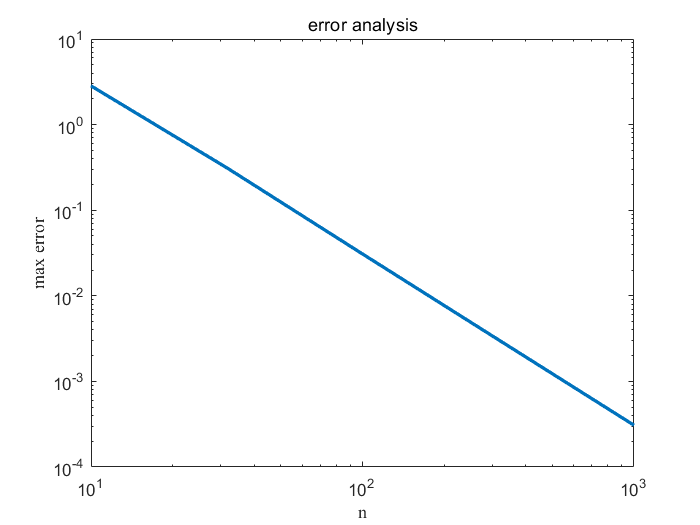



m = zeros(1,6);
for i= 1:6
    n = round(10^(0.5+i/2));
    xn = 1;x0 = 0;
    h = (xn-x0)/n;
    A0 = [1,zeros(1,n)];
    A1 = [diag(ones(1,n-1)) , zeros(n-1,2)];
    A2 = [zeros(n-1,1),diag(ones(1,n-1))*(10*h^2-2) , zeros(n-1,1)];
    A3 = [zeros(n-1,2),diag(ones(1,n-1))];
    A4 = [zeros(1,n),1];
    A = [A0;A1+A2+A3;A4];
    b = [zeros(n,1);1];
    y = A\b;
    
    syms Y(t)
    cond = [Y(0) == 0,Y(1)==1];
    f = dsolve(diff(Y,t,2) == -10*Y,cond);
    f = matlabFunction(f);
    x = x0:h:xn;
    error = abs((y'-f(x)));
    my_error = max(error);
    m(i) = my_error;
end
i= 1:6;
n = round(10.^(i/2));
loglog(n,m,"LineWidth",2);
xlim([10,1000])
title('error analysis')
xlabel('n','Fontname','Times New Roman')
ylabel('max error','Fontname','Times New Roman')